# Read Streaming Data from Arduino Using Serial Port Communication

This example shows how to enable callbacks to read streaming ASCII terminated data from an Arduino`®` board using the `serialport` interface. 

This example uses an Arduino Due; however, most Arduino boards should work.

## Upload a Program to the Arduino

Plug in an Arduino board to your computer.

Upload the following program to the Arduino`®` board using the Arduino IDE. This program writes out continuous points of a sine wave, followed by the "Carriage Return" and "Linefeed" terminators.

## Establish a Connection to the Arduino

In MATLAB, close all existing `serialport `connections.

delete(serialportfind);

Find the serial port that the Arduino is connected to. You can identify the port from the Arduino IDE. For this example, suppose that the Arduino IDE indicates that the connection is at port `COM4`. Confirm that this port exists on your machine by listing all available ports.

serialportlist("available")

Connect to the Arduino Due by creating a `serialport` object. Use the port and baud specified in the Arduino code.

serialObj = serialport("COM4",9600)

## Prepare the `serialport` Object to Start Streaming Data

Configure the `serialport` object by configuring its properties and clearing old data.

Set the `Terminator` property to match the terminator that you specified in the Arduino code.

configureTerminator(serialObj,"CR/LF");

Flush the `serialport` object to remove any old data.

flush(serialObj);

Prepare the `UserData` property to store the Arduino data. In this case, define `UserData` to be a struct in which the `Data` field contains sine wave values and `Count` records the number of data points collected. This structure allows for organized and efficient access and updating of these related pieces of information.

serialObj.UserData = struct("Data",[],"Count",1)

In a new MATLAB file, create a callback function `readSineWaveData` that reads the first 1000 ASCII terminated sine wave data points and plots the result. This function takes in an argument `maxDataPoints` that determines when to plot the data. 

Configure the serial port object to execute the `readSineWaveData` function whenever new data, indicated by the terminator, is available to read from the Arduino. The following `configureCallback` command sets the `BytesAvailableFcnMode` to "terminator" and the `BytesAvailableFcn` property to a handle to `readSineWaveData` function.

maxDataPoints = 1002; 
configureCallback(serialObj, "terminator", @(src,event) readSineWaveData(src,event,maxDataPoints))

The callback function opens the MATLAB figure with a plot of the first 1000 data points.

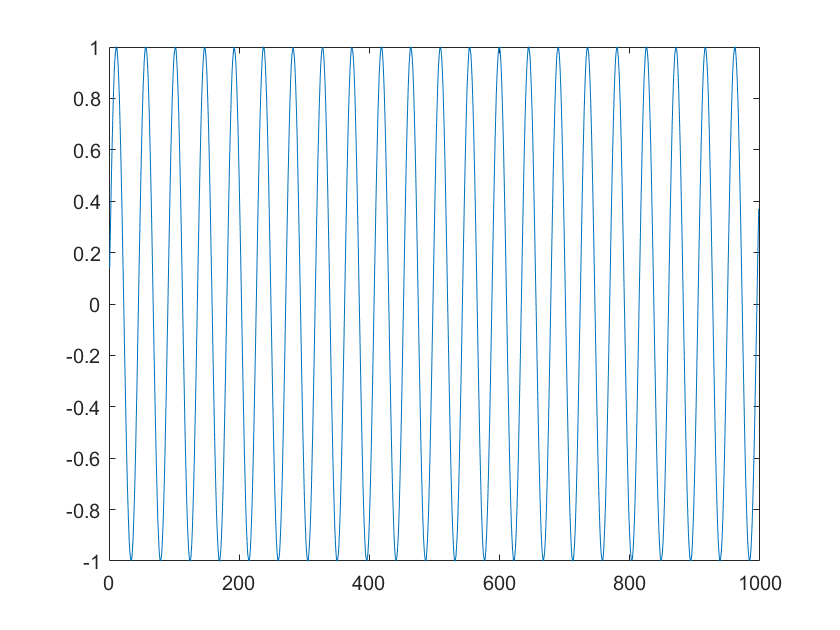

*Copyright 2024 The MathWorks, Inc.*